clc
clear
syms ws wp I theta real
omega_af = [0; 0; wp];
omega_bf = [0; ws; 0];
%Transfer function from airframe frame to body frame
Rafb = Ry(theta)

$$Rafb = \left(\begin{array}{ccc} \cos\left(\frac{\pi \,\theta }{180}\right) & 0 & \sin\left(\frac{\pi \,\theta }{180}\right)\\ 0 & 1 & 0\\ -\sin\left(\frac{\pi \,\theta }{180}\right) & 0 & \cos\left(\frac{\pi \,\theta }{180}\right) \end{array}\right)$$

%Total angular velocity in body frame
omega_B = Rafb \ omega_af + omega_bf;

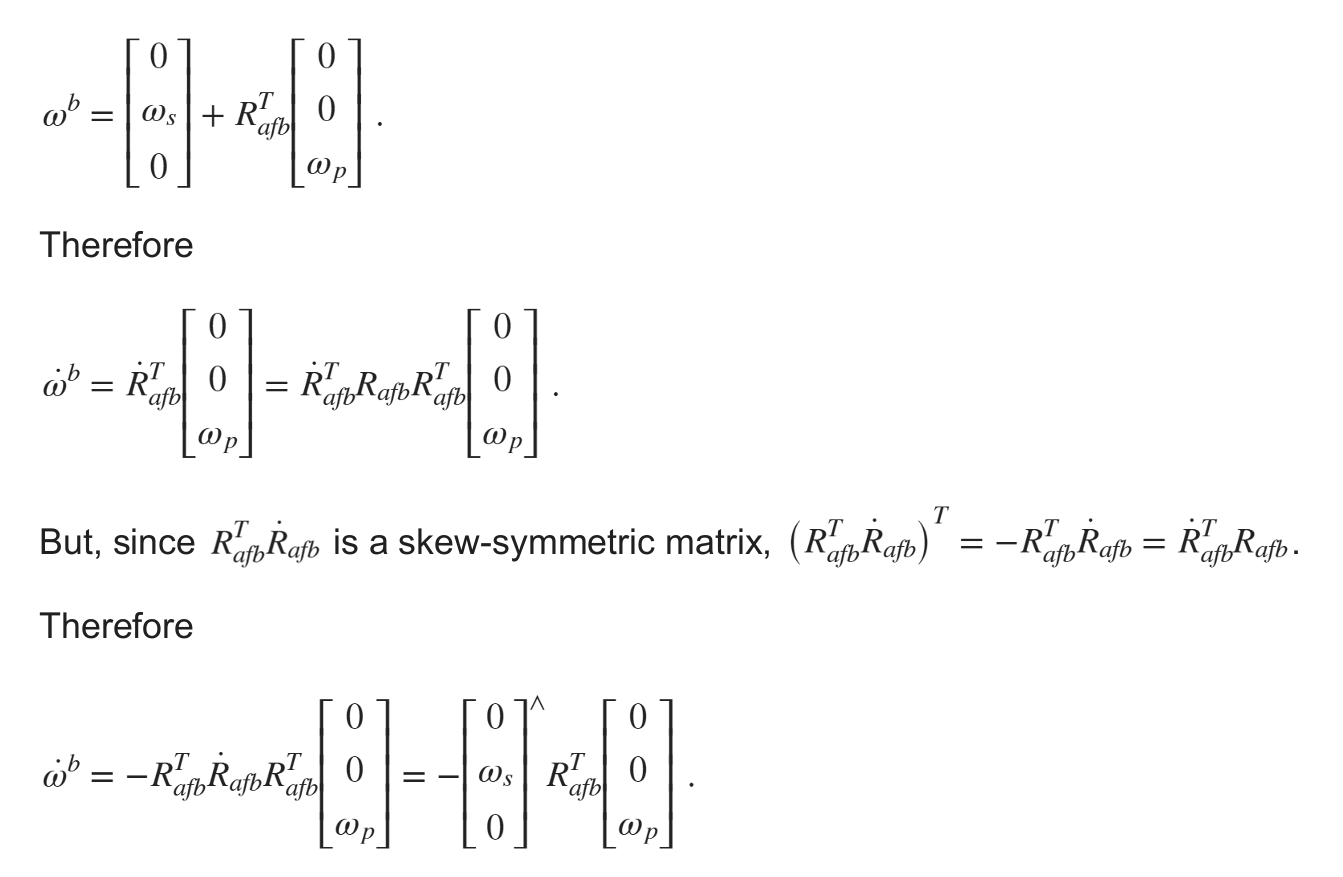

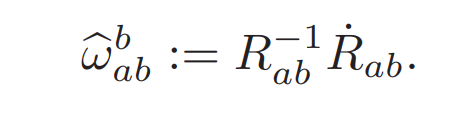

alpha_B = -hat(omega_bf)*Rafb'*omega_af

$$alpha\_B = \left(\begin{array}{c} -\mathrm{wp}\,\mathrm{ws}\,\cos\left(\frac{\pi \,\theta }{180}\right)\\ 0\\ -\mathrm{wp}\,\mathrm{ws}\,\sin\left(\frac{\pi \,\theta }{180}\right) \end{array}\right)$$

%from part we know Ia
Ia = [I, 0, 0;
      0, I, 0;
      0, 0, 0];

%Newton-Euler equation in body coordinates
tuob = subs(Ia*alpha_B + hat(omega_B)*Ia*omega_B, theta,0)

$$tuob = \left(\begin{array}{c} -2\,\text{I}\,\mathrm{wp}\,\mathrm{ws}\\ 0\\ 0 \end{array}\right)$$

tuoa = subs(Rafb*tuob, theta,0)

$$tuoa = \left(\begin{array}{c} -2\,\text{I}\,\mathrm{wp}\,\mathrm{ws}\\ 0\\ 0 \end{array}\right)$$

% when theta equal 0
tuoa = double(subs(tuoa, {wp,ws,I}, {0.1,420,2.26}))

tuoa =  -189.8400
         0
         0


tuob = double(subs(tuob,{wp,ws,I}, {0.1,420,2.26}))

tuob =  -189.8400
         0
         0


%when theta equal to pi/4
tuob2 = subs(Ia*alpha_B + hat(omega_B)*Ia*omega_B, theta,45)

$$tuob2 = \left(\begin{array}{c} -\sqrt{2}\,\text{I}\,\mathrm{wp}\,\mathrm{ws}\\ -\frac{\text{I}\,{\mathrm{wp}}^{2}}{2}\\ 0 \end{array}\right)$$

tuoa2 = subs(Rafb*tuob, theta,45)

$$tuoa2 = \left(\begin{array}{c} -\frac{2373\,\sqrt{2}}{25}\\ 0\\ \frac{2373\,\sqrt{2}}{25} \end{array}\right)$$

tuoa2 = double(subs(tuoa2, {wp,ws,I}, {0.1,420,2.26}))

tuoa2 =  -134.2372
         0
  134.2372


tuob2 = double(subs(tuob2,{wp,ws,I}, {0.1,420,2.26}))

tuob2 =  -134.2372
   -0.0113
         0


%when theta equal to 90 degree
tuob3 = subs(Ia*alpha_B + hat(omega_B)*Ia*omega_B, theta,90)

$$tuob3 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

tuoa3 = subs(Rafb*tuob3, theta,90)

$$tuoa3 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

tuoa3 = double(subs(tuoa3, {wp,ws,I}, {0.1,420,2.26}))

tuoa3 =      0
     0
     0


tuob3 = double(subs(tuob3,{wp,ws,I}, {0.1,420,2.26}))

tuob3 =      0
     0
     0



function R_y = Ry(theta)
         theta = deg2rad(theta);
         R_y = [cos(theta), 0, sin(theta);
                0, 1, 0;
                -sin(theta), 0, cos(theta)];
end

function u_hat = hat(u)
    % 3维向量的反对称矩阵 (Wedge/Hat 变换)
    u_hat = [    0, -u(3),  u(2);
              u(3),     0, -u(1);
             -u(2),  u(1),     0];
end